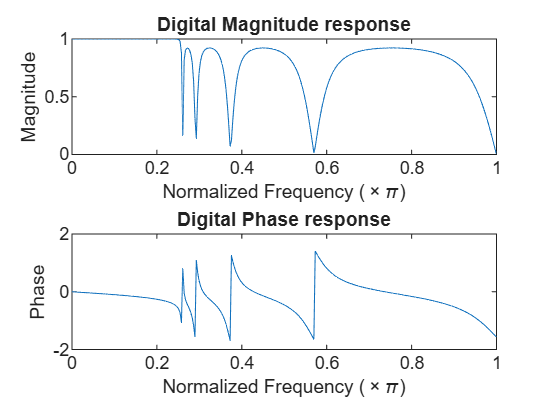

clc;
clear all;
close all;

fs=700;

[b,a]=cheby1(9,0.7,90/(fs/2),'low');   % normalized cutoff

w=0:0.01:pi;   % digital frequency range

[h,w]=freqz(b,a,w);


subplot(2,1,1);
plot(w/pi,abs(h));
xlabel('Normalized Frequency (\times\pi)');
ylabel('Magnitude');
title('Digital Magnitude response');

subplot(2,1,2);
plot(w/pi,angle(h));
xlabel('Normalized Frequency (\times\pi)');
ylabel('Phase');
title('Digital Phase response');